# **Cross-validazione**

## **Reset del workspace**

addpath ..\..\'D-STEM v2.1'\Src\
addpath ..\..\'D-STEM v2.1'\Src\fda\

clear all %#ok<CLALL> 
clc

## Importazione dei dati

data = load("..\Data\Processed data\Hourly_data.mat").hourly_data;

## Subset dei dati originali

al fine di ottenere delle stime del parametro rho più significative si semplifica il modello escludendo tutte le covariate ad eccezione di quella costante e si ristringe il domino temporale ai soli mesi di giugno e lugio ( i mesi caratterizzati da una maggiore frequenza dei noleggi di biciclette)

% Definizione delle date di inizio e fine
data_inizio_anno = datetime(2020, 1, 1); % 1 gennaio 2020
data_inizio_periodo = datetime(2020, 5, 31); % 31 maggio 2020
data_fine_periodo = datetime(2020, 7, 31); % 31 luglio 2020

% Calcolare i delta giornalieri
n_giorni_start = days(data_inizio_periodo - data_inizio_anno) + 1;
n_giorni_end = days(data_fine_periodo - data_inizio_periodo);

%subset di data
data = data((n_giorni_start*51) +1 : (n_giorni_start + n_giorni_end) * 51, [data.Properties.VariableNames(1:5), ...
    data.Properties.VariableNames(16:end)]);

## Cross-validazione

### Scelta dei fold

rng('default')
k = 5;
n = size(unique(data(:, ["X_coordinate", "Y_coordinate"])), 1);
l = floor(n/k);
S_val = randsample(n, n)';
partitions = cell(k, 1);
for i=1:k
    partitions{i} = S_val(1, l*(i-1)+1:l*i);
end
if k*l - n ~= 0
    partitions{k} = [partitions{k} S_val(1, k*l+1:end)];
end

### Avvio

rho_to_test = 0:.002:.6;
MSE_summary.not_round = zeros(length(rho_to_test), k);
MSE_summary.round = zeros(length(rho_to_test), k);

for i=1:length(rho_to_test)
    
    for j=1:k
        
        disp("rho = " + num2str(rho_to_test(i)) + ", partition " + num2str(j) + " of " + num2str(k))
        disp("-----------")

        % scelta del modello
        o_modeltype = stem_modeltype('f-HDGM');
        o_modeltype.flag_potential = true;
        
        % creazione dell'oggetto stem_fda
        input_fda.spline_type = 'Fourier';
        input_fda.spline_range = [0 24];
        input_fda.spline_nbasis_z = 7;
        input_fda.spline_nbasis_beta = 5; 
        input_fda.spline_nbasis_sigma = 5;
        o_fda = stem_fda(input_fda);
    
        % creazione dell'oggetto stem_data
        input_data.stem_modeltype = o_modeltype;
        input_data.data_table = data;
        input_data.stem_fda = o_fda;
        o_data = stem_data(input_data);
    
        % creazione dell'oggetto stem_validation
        o_data.stem_validation = stem_validation('pickups', partitions{j});
    
        % creazione dell'oggetto stem_model
        o_par = stem_par(o_data, 'exponential');
        o_model = stem_model(o_data, o_par);
    
        % inizializzazione manuale dei parametri
        o_par.rho = rho_to_test(i);
        n_basis=o_fda.get_basis_number;
        o_par.theta_z = ones(1,n_basis.z)*.01;
        o_par.G = diag(ones(n_basis.z,1)*.5);
        o_par.v_z = eye(n_basis.z)*.5;
        
        % inizializzazione automatica dei parametri
        T = size(o_model.stem_data.Y, 2);
        n = size(o_model.stem_data.stem_gridlist_p.grid{1, 1}.coordinate, 1);
        q = o_model.stem_par.q;
        o_model.set_distance_matrix
        Y = o_model.stem_data.Y;
    
        % depotenziamento dei dati originali
        diag_H_inv = stem_misc.compute_H_inv(o_model.DistMat_rho, ...
            q, o_par.rho);
        Y_pot = zeros(size(o_model.stem_data.Y));
        for t=1:T
            Y_pot(:, t) = diag_H_inv.*Y(:, t);
        end
    
        % inizializzazione di beta e di sigma_eps
        o_model.stem_data.stem_varset_p.Y = mat2cell(Y_pot, n.*ones(1, q));
        o_model.stem_data.Y = Y_pot;
        o_par.beta = o_model.get_beta0();
        o_par.sigma_eps = o_model.get_coe_log_sigma_eps0();
        
        %% ripristino dei dati originali
        o_model.stem_data.stem_varset_p.Y = mat2cell(Y, n.*ones(1, q));
        o_model.stem_data.Y = Y;
        o_model.set_initial_values(o_par);
        
        % stima EM del modello
        o_EM_options = stem_EM_options();
        o_EM_options.exit_tol_par = 0.0001; 
        o_EM_options.exit_tol_loglike = 0.0001; 
        o_EM_options.max_iterations = 50;
        o_model.EM_estimate(o_EM_options);
    
        % salvataggio dei risultati

        %% senza arrotondamento
        MSE_summary.not_round(i, j) = mean(o_model.stem_validation_result.cv_mse_s);

        %% con arrotondamento
        l_j = size(o_model.stem_validation_result.y_hat_back{1}, 1);
        y_hat_back = o_model.stem_validation_result.y_hat_back;
        y_back = o_model.stem_validation_result.y_back;
        MSE_round = zeros(1, l_j);
        for k_in=1:l_j
            res_k = [];
            for w=1:q
                res_k = [res_k; y_back{w}(k_in, :) - round(y_hat_back{w}(k_in, :))]; %#ok<AGROW> 
            end
            MSE_round(k_in) = mean(res_k(:).^2);
        end
        MSE_summary.round(i, j) = mean(MSE_round);
    
        clear o_data o_EM_options o_fda o_model o_modeltype o_par

    end

end

rho = 0, partition 1 of 5


-----------


 
**********************************************
*   Data description of stem_varset object   *
**********************************************
Maximum number of observations per profile: q=24
 
Number of spatial locations: n=51
 
Number of time steps: T=61
 
Generating data matrices...
Generation ended.
Looking for duplicated sites...
Operation ended.


Generating data matrices...
Generation ended.


Generating point distance matrices...
Generation ended.


Generating point distance matrices...
Generation ended.
Data modification for validation started...
******************
Cropping sites...
Cropping ended.
******************
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
Data modification ended.
 
**********************
*   D-STEM version   *
**********************
 
Model estimation is performed using D-STEM v2
 
******************************
*   Brief data description   *
******************************
Number of variables: q=24
 
Point variables:
sum of points for each variable: Nq=984
sum of sites for each variable: N=41
 
Date and time steps:
  Stating date  : 01-Jun-2020
  Ending date   : 31-Jul-2020
  Temporal steps: 61
 
Bounding box of the point data:
  Latitude min : 40.71 deg
  Latitude max : 40.75 deg
  Longitude min: -74.08 deg
  Longitude max: -74.03 deg
 
Number of latent variables: p=7
 
Covariates related to beta:
    {'const'}

************************
Iteration 1 s

## Caricamento dei risultati di Cross validazione

addpath ..\Results\
MSE_002=load ('MSE_summary_rho_0_002_06');
MSE_0005=load ('MSE_summary_0005_0005_0015');

## Plot dei risultati

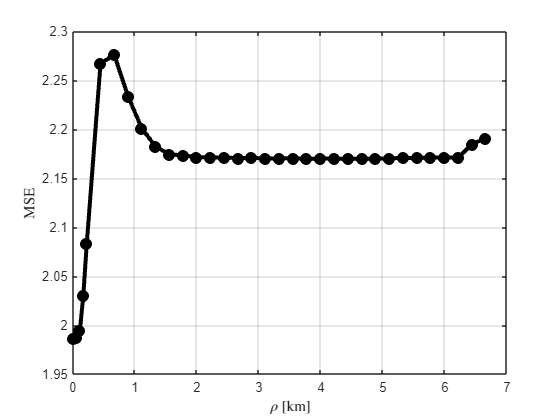


% estrazione delle prime 31 righe (rho che va da 0 a 0.06 con passo 0.002)
MSE_not_round=MSE_002.MSE_summary.not_round(1:31,:);
MSE_round=MSE_002.MSE_summary.round(1:31,:);

MSE_not_round_0005=MSE_0005.MSE_summary.not_round;
MSE_round_0005=MSE_0005.MSE_summary.round;

MSE_not_round = [MSE_not_round(1,:);MSE_not_round_0005;MSE_not_round(2:end,:)];
MSE_round = [MSE_round(1,:);MSE_round_0005;MSE_round(2:end,:)];
% calcolo della media del MSE per ogni rho testato
MSE_mean_not_round = mean(MSE_not_round,2);
MSE_mean_round = mean(MSE_round,2);


% definizine del vettore rho corrispondente in Km
rho_values = [0:.0005:.002, .004:.002:.06];
rho_values = rho_values.*111;

% Grafico not round
plot(rho_values, MSE_mean_not_round, '-O', 'LineWidth', 3,'MarkerFaceColor', 'black','Color', 'black');
xlabel('$\rho$ [km]','Interpreter', 'latex');
ylabel('MSE','Interpreter', 'latex');
gx.LongitudeLabel.Interpreter = "latex";
grid on;

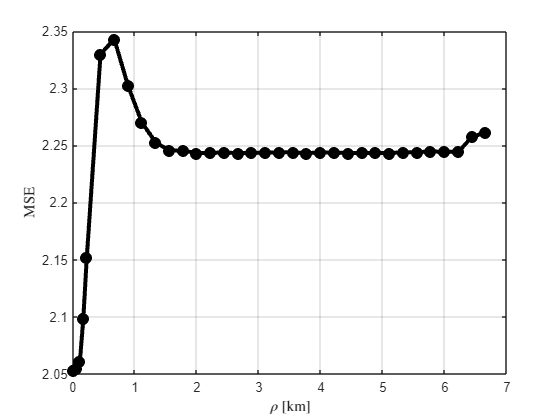

% Grafico round
plot(rho_values, MSE_mean_round, '-O', 'LineWidth', 3,'MarkerFaceColor', 'black','Color', 'black');
xlabel('$\rho$ [km]','Interpreter', 'latex');
ylabel('MSE','Interpreter', 'latex');
gx.LongitudeLabel.Interpreter = "latex";
grid on;

## Plot risultati modello Subeset

MSE_sub=load ('MSE_summary_0_001_1.mat');
MSE_mean_sub = mean(MSE_sub,2);

Error using sum
Invalid data type. First argument must be numeric or logical.

Error in mean (line 125)
        y = sum(x, dim, flag) ./ mysize(x,dim);